Data 

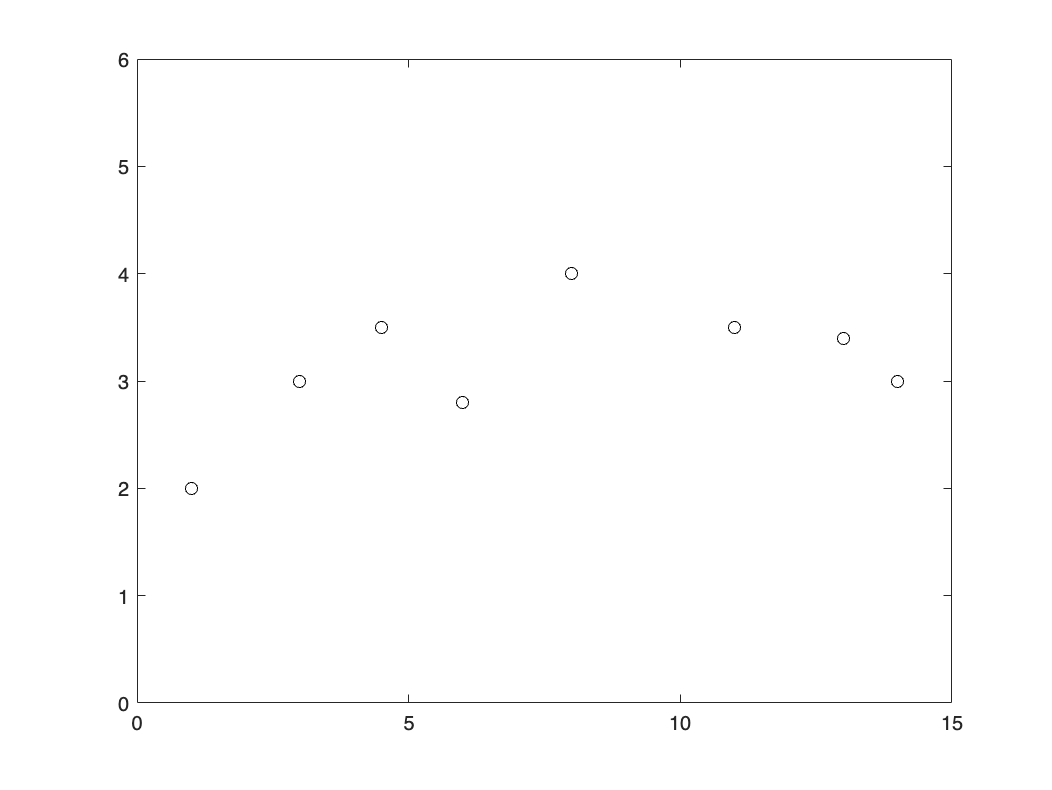

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

figure
plot(x, y, 'kO')
hold on
axis([0 15 0 6])

Linear interpolation (points 1 & 8)

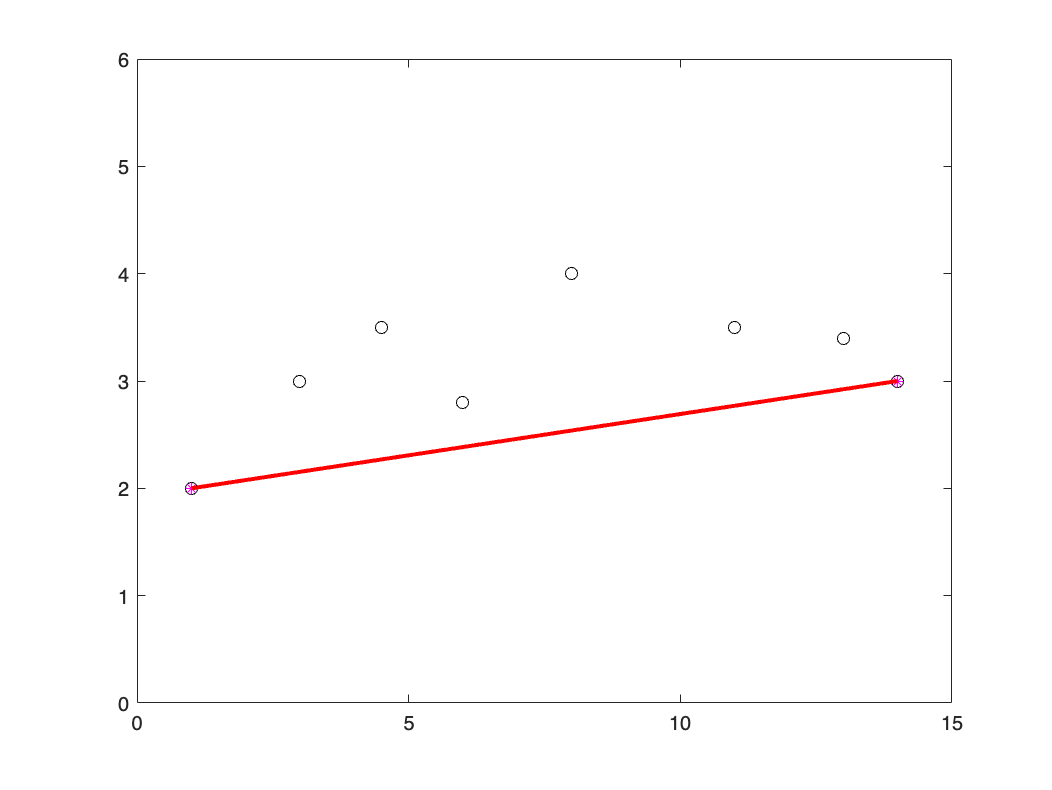

xx = [x(1)   x(8)]; 
yy = [y(1)   y(8)];

p1 = polyfit(xx, yy, 1);

xxx = 1:0.1:14;
yyy1 = polyval(p1, xxx);

figure
plot(x, y, 'kO')
hold on
plot(xx, yy, 'm*')
hold on
plot(xxx, yyy1, 'r-', 'LineWidth', 2)
axis([0 15 0 6])

Quadratic polynomial interpolation (points 1,5,8)

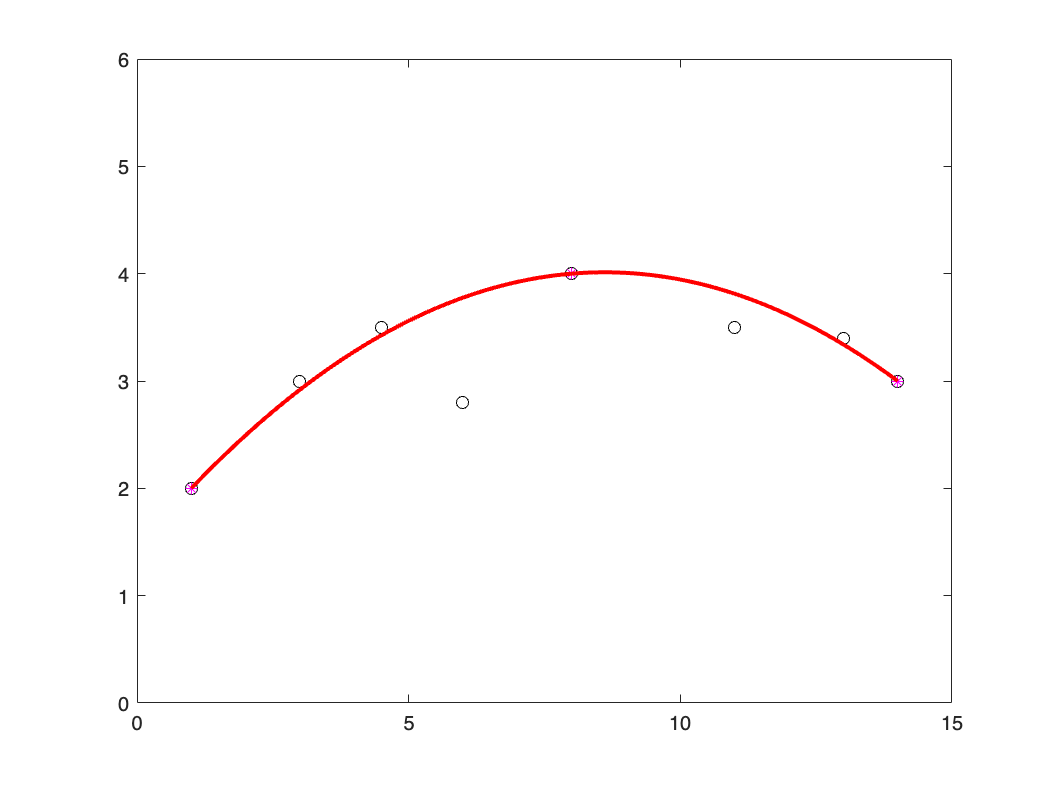

xx = [x(1)   x(5)    x(8)];
yy = [y(1)   y(5)    y(8)];

p2 = polyfit(xx, yy, 2);

xxx = 1:0.1:14;
yyy2 = polyval(p2, xxx);

figure
plot(x, y, 'kO')
hold on
plot(xx, yy, 'm*')
hold on
plot(xxx, yyy2, 'r-', 'LineWidth', 2)
axis([0 15 0 6])

Cubic polynomial interpolation (points 1,3,6,8)

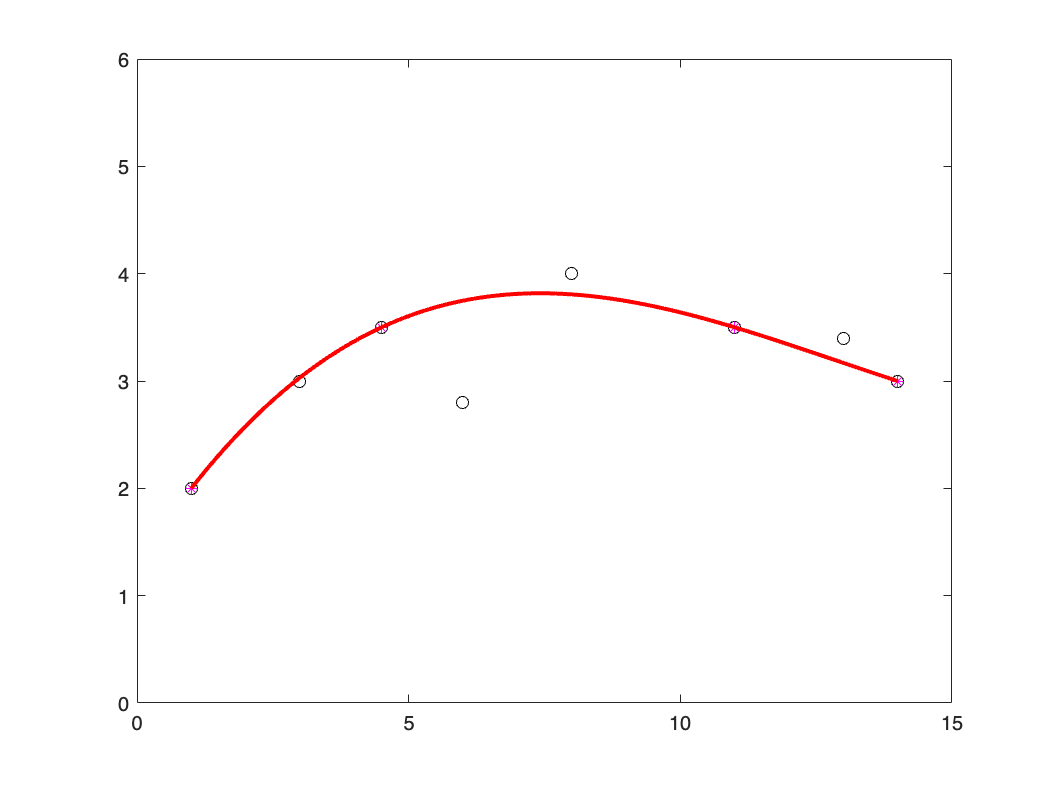

xx = [x(1)   x(3)    x(6)    x(8)];
yy = [y(1)   y(3)    y(6)    y(8)];

p3 = polyfit(xx, yy, 3);

xxx = 1:0.1:14;
yyy3 = polyval(p3, xxx);

figure
plot(x, y, 'kO')
hold on
plot(xx, yy, 'm*')
hold on
plot(xxx, yyy3, 'r-', 'LineWidth', 2)
axis([0 15 0 6])

7th-order polynomial interpolation

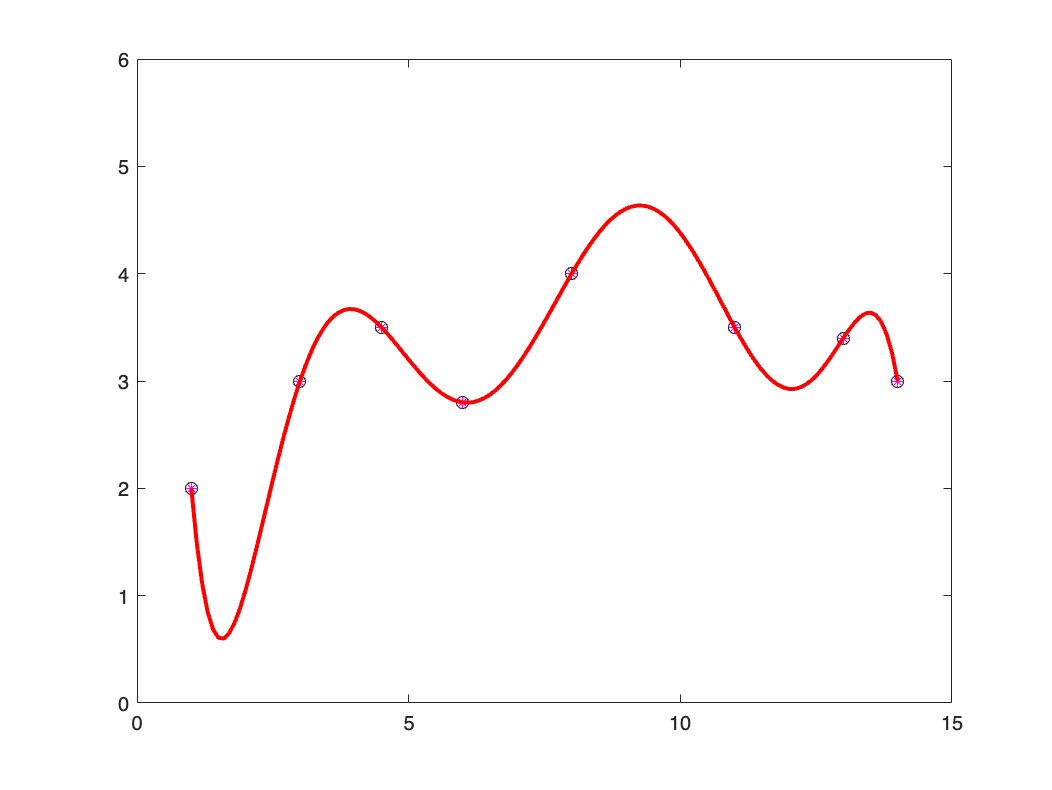

xx = x;
yy = y;

p7 = polyfit(xx, yy, 7);

xxx = 1:0.1:14;
yyy7 = polyval(p7, xxx);

figure
plot(x, y, 'kO')
hold on
plot(xx, yy, 'm*')
hold on
plot(xxx, yyy7, 'r-', 'LineWidth', 2)
axis([0 15 0 6])